# Balsitic trajectory simulator

simulates the trajectory of artillery shells fired on a basitic trajectory.

clear; close; clc;
% Inictial condition
x_0 = 0;
z_0 = 0;
t_0 = 0;

% Boundary values
%x_f = %range
z_f = 0;


% 9 dof simulator (inop)
% equation of motion
% vdot = (F - v * mdot) / m %maybe?

% X = [x; y; z];
% 
% V = [v_x; v_y; v_z];
% 
% omega_b = [P; Q; R];
% 
% % compute force of gravity
% F_g = 6.6743E-11 * (5.9722E24)*m / (6371E3 + alt)^2 % gravity = G * m_e * m_missile / (r_e+alt)^2
% 
% HIB = HIB(Theta) % find rotation matrix
% HBI = transpose(HIB(Theta)); % invert the rotation matrix
% 
% vdot = 1/m *( HBI * F_ap_body + F_g - HIB * omega_tilde_body * (m*v) - mdot*v)



% ballistics calculator 2D


%CARTRIDGE, 105-MILLIMETER: HERA, M913
Hydrolic_Diameter = 0.105; %m
Nozzle_Exit_Diameter = Hydrolic_Diameter * .5/7; %m
Projectile_Length = 0.547; %m
Nose_Length = 0.410; %m
Boattail_Diameter = Hydrolic_Diameter * 5.7/7; %m

Nozzle_Exit_Area = pi * (Nozzle_Exit_Diameter/2)^2;

Projectile_Mass = 13.3 %kg <= 29.55lbf I have selected this

Projectile_Mass = 13.3000


%some guesses
Impulse_Specific = 250 %s

Impulse_Specific = 250

Propellant_Mass =  1.13 %kg <= 2.2 lbf 

Propellant_Mass = 1.1300


%motor details
Motor_On_Time = 16;
Motor_Off_Time = 18;
%Motor_Off_Time = 14;

%launch conditions
%z_0 = -3660; %m
V_muzzle = 625; %m/s
Gun_Elevation = deg2rad(45);

%xi = atan2(-v_z, v_x); % calculate flight path angle
v_x_0 = V_muzzle * cos(Gun_Elevation);
v_z_0 = V_muzzle * sin(-Gun_Elevation);

V = [v_x_0, v_z_0];
X = [x_0, z_0];
m = Projectile_Mass;

% parameters need for simulation
state = [V,X,m]

state =   441.9417 -441.9417         0         0   13.3000


tspan = [0 300]

tspan =      0   300



% simulate the flight
options = odeset(Refine=32); % increase the number of output points so we dont miss the x intercept.
[rawT,rawStates] = ode45(@(t,y) dynamics(t,y,Projectile_Length,Nose_Length,Hydrolic_Diameter, Boattail_Diameter, Nozzle_Exit_Area,Motor_On_Time, Motor_Off_Time, Propellant_Mass, Impulse_Specific), tspan, state, options);

% remove states after the bullet has hit the ground (these dont exist)
flyingStates = rawStates(:,4) <= 0;
states = rawStates(flyingStates,:);
t = rawT(flyingStates);

V = states(:,1:2);
X = states(:,3:4);
m = states(:,5);

range = X(end,1)

range = 2.0544e+04

TOF = t(end)

TOF = 72.2125

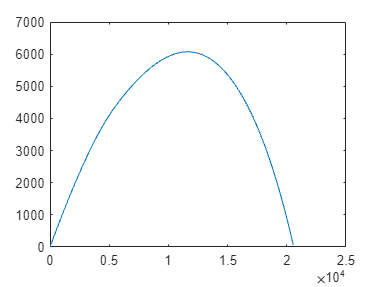


plot(X(:,1),-X(:,2));

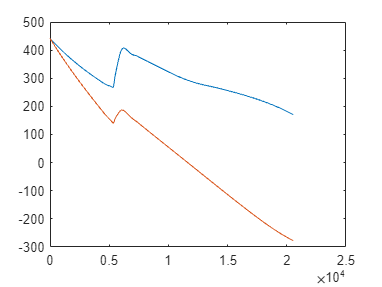

plot(X(:,1),[V(:,1),-V(:,2)]);

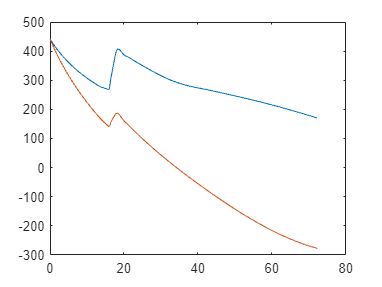

plot(t(:),[V(:,1),-V(:,2)]);

function dydt = dynamics(t,y,l,l_N,d,d_bt, A_e, time_ThrustStart, time_ThrustStop, Propellant_mass, I_sp)
    V = y(1:2);
    X = y(3:4);
    m = y(5);

    g_0 = 9.81; %m/s g_0 is accel due to gravity on earth surface 
    
    % compute mass and forces

    % compute thrust and account for reduction in drag due to thrust
    if t > time_ThrustStart && t < time_ThrustStop % mototr is on
        %compute mass flow rate
        mdot = Propellant_mass / (time_ThrustStop - time_ThrustStart);

        %compute forces impacted by thrust
        F_propulsion = V/norm(V) * I_sp * g_0 * mdot;
        F_drag = -V/norm(V) * drag_body(-X(2), norm(V), l, l_N, d, d_bt, A_e, false); % balistic trajectory -> pointing in direction of velociy
    
    else % motor is off
        %compute mass flow rate
        mdot = 0; % no fuel burn no mass change

        %compute forces impacted by thrust
        F_propulsion = V/norm(V) *0;
        F_drag = -V/norm(V) * drag_body(-X(2), norm(V), l, l_N, d, d_bt, A_e, true); % balistic trajectory -> pointing in direction of velociy
    end

    F_g = [0;1] * 6.6743E-11 * (5.9722E24)*m / (6371E3 - X(2))^2; % gravity = G * m_e * m_missile / (r_e+alt)^2

    % net force
    F_net = F_drag + F_propulsion + F_g;

    % equation of motion
    Vdot = (F_net - V * mdot) / m;

    % position
    Xdot = V;

    dydt = [Vdot;Xdot;mdot];

end
